# Numerical Analysis Homework #1

## Problem #1:

Solve $x^3-3x-1=0$ using Newton's method of approximations:

The exuation to the tangent line is given by $f\left(x\right)=\mathrm{f'}\left(x_0 \right)∗\left(x-x_0 \right)+f\left(x_0 \right)$.

We want to find $x$ such that $f\left(x\right)=0$. If $x$ is a solution such that $f\left(x_0 \right)=0$, then $0=\mathrm{f'}\left(x_0 \right)∗\left(x-x_0 \right)+f\left(x_0 \right)$. Some algebra gives the equation

$x_1=x_0-\frac{f(x_0)}{f'(x_0)}$. The intuition here being that $x_1$ will be a better guess than $x_0$.

In a generalized form we have $x_{n+1} = x_n-\frac{f(x_n)}{f'(x_n)}$, the solution to which can be easily implemented in a loop.

tolerance = 1e-20;   %Something really small, assuring our answer will be close
xGuess = 0;          %Doesn't really matter what you choose...
fValue = 10;
xZero=0;

while abs(fValue) > tolerance
    %From the generalized equation above, since we know the derivative
    xZero = xGuess - (xGuess^3 - 3*xGuess - 1) / (3*xGuess - 3);
    fValue = xZero^3-3*xZero-1;
    xGuess=xZero;
end
xZero

xZero = -0.3473

Let's check to make sure this answer is correct.

xZero^3-3*xZero-1

ans = 0

## Problem #2:

Solve $\int_{0}^{\frac{\pi}{4}}{tan(x)dx}$ using the Reimann sum method:

Reimann sum is fairly straightforward. Add all "slices" of $\mathrm{tan}\left(x\right)$evaluated at the appropriate $x$ value with a width of $\frac{\pi/4-0}{n}$.

n=1000;     %Should ne high enough to get a reasonable approximation
total=0;    %Start off at 0
for i = 1:n
    total = total + tan(i*pi/(4*n))*pi/(4*n);
end
total

total = 0.3470

## Problem #3:

Find $\mathrm{f'}\left(x\right)$ for$f(x)=\frac{x-1}{x+2}$ on $0<x<1$.

With this approximation method, the derivative can be found by finding the difference between $f\left(x\right)$ and $f\left(x+h\right)$ for $h$ small.

In loop form for this will look like $f'(x)=g(x)=\sum f(i) = n *\sum_{i=0}^{n} 
$ $\frac{x_{i+1}*\frac{1}{n}-1}{x_{i+1}*\frac{1}{n}+2}} - \frac{x_{i+1}*\frac{1}{n}-1}{x_{i+1}*\frac{1}{n}+2}} * \frac{1}{n}$ $-$ $\frac{x_{i}*\frac{1}{n}-1}{x_{i}*\frac{1}{n}+2}} - \frac{x_{i}*\frac{1}{n}-1}{x_{i}*\frac{1}{n}+2}} * \frac{1}{n}$ for this particular equation.

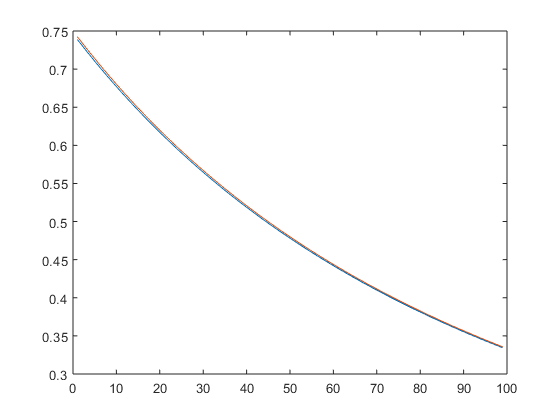

n=100;
for i = 1:n-1
    x(i) = i;
    f(i) = (((i+1)/n-1)/((i+1)/n+2)-(i/n-1)/(i/n+2))*n;
    %Check using derivative taken by hand
    g(i) = (3/(i/n+2)^2);
end
plot(x,f,x,g)